# Hodgkin-Huxley with Extinction Current Pulses

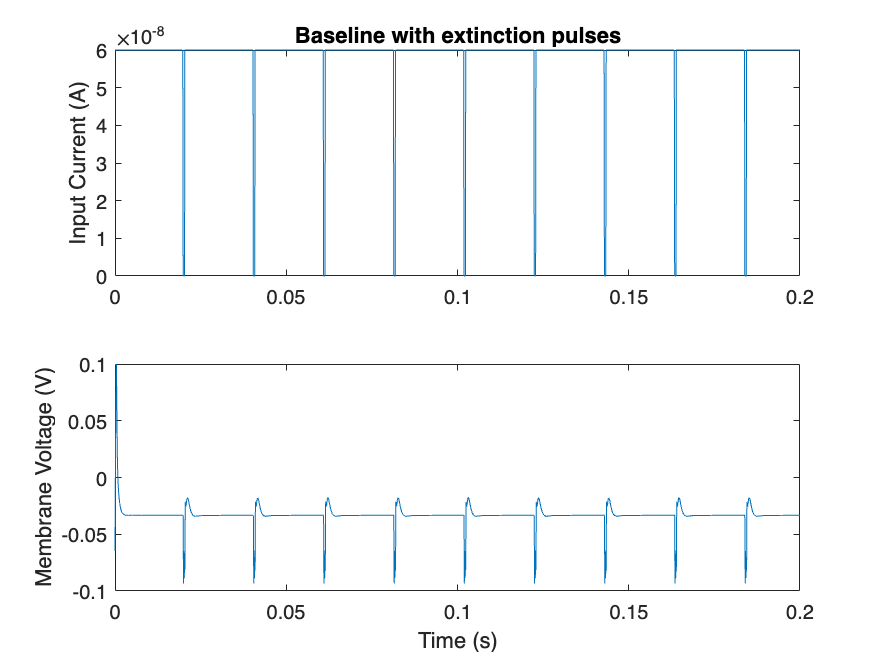

% Declare Global Parameter Values
Gl = 30e-9; % in Siemens
GNa = 12e-6; % in Siemens
Gk = 3.6e-6; % in Siemens
ENa = 45e-3; % in Volts (V)
Ek = -82e-3; % in V
El = -60e-3; % in V
Cm = 100e-12; % in Farads

% Set up time vector
t0 = 0;
dt = 0.1e-3;
t_max = .35; % in seconds
tvec = t0:dt:t_max;

% Create membrane potential vector
Vd = zeros(size(tvec));
% Call function applied current 2 to generate step pulse current with
% parameters pulses = 10, baseline current= 0.6 nA, pulse duration = 5 ms, delay btwn pulse = 20ms.
APC2 = applied_current2(tvec, 10, 0.6e-7,5,0,200); %Applied current vector
% Create gating variable vectors
md = zeros(size(tvec));
hd = zeros(size(tvec));
nd = zeros(size(tvec));

% Initial Conditions
Vd(1) = -65e-3;
md(1) = 0.05;
hd(1) = 0.05;
nd(1) = 0.35;

% Run Euler's Method
for i = 2:length(tvec)
    dVddt = (1/Cm)*(Gl*(El-Vd(i-1)) + GNa*(md(i-1)^3)*hd(i-1)*(ENa - Vd(i-1)) + Gk*(nd(i-1)^4)*(Ek-Vd(i-1)) + APC2(i-1));
    Vd(i) = EM(Vd(i-1), dVddt, dt);
    dmddt = alphaM(Vd(i-1))*(1-md(i-1)) - betaM(Vd(i-1))*md(i-1);
    md(i) = EM(md(i-1), dmddt, dt);
    dhddt = alphaH(Vd(i-1))*(1-hd(i-1)) - betaH(Vd(i-1))*hd(i-1);
    hd(i) = EM(hd(i-1), dhddt, dt);
    dnddt = alphaN(Vd(i-1))*(1-nd(i-1)) - betaN(Vd(i-1))*nd(i-1);
    nd(i) = EM(nd(i-1), dnddt, dt);
end

% Plot Figures
figure;
subplot(2,1,1)
x = tvec;
y1 = APC2;
plot(x, y1)
xlim([0 0.2]);
title('Baseline with Extinction Pulses')
ylabel('Input Current (A)')
subplot(2,1,2)
y2 = Vd;
plot(x, y2)
xlim([0 0.2]);
xlabel('Time (s)')
ylabel('Membrane Voltage (V)')

function applied_current_vector2 = applied_current2(tvec, pulses, baseline,duration, amplitude, delay)
% This modified version of applied current vector takes tvec, number of
% pulses, a baseline current, desired pulse duration, amplitude, and
% delay and generates a current vector with uniformly delayed pulses and
% is used in 1D.
% Initialize the output vector to zeros
    applied_current_vector2 = ones(size(tvec));
    applied_current_vector2 = applied_current_vector2.*baseline; % set baseline current
    delay_times = delay; % constant delay
% Loop through each pulse
    for i = 1:pulses
    % Find the start time of the current pulse
    if i == 1
    start_time = delay_times;
    else
    start_time = start_time + duration + delay_times;
    end
    % Set the values of applied_current_vector to amplitude during the pulse
    applied_current_vector2(start_time : start_time+duration-1) = amplitude;
    end
end
function y = EM(a, b, c) %Euler's Method Function
y = a + b*c;
end
function y = alphaM(x)
if exp(100*(-x-0.045))-1 == 0 % Checks for division by zero to prevent
errors
y = 0;
else
y = ((10^5)*(-x-0.045))/(exp(100*(-x-0.045))-1);
end
end
function y = betaM(x)
y = 4*(10^3)*exp((-x-0.070)/0.018);
end
function y = alphaH(x)
y = 70*exp(50*(-x-0.070));
end
function y = betaH(x)
y = 10^3/(1 + exp(100*(-x-0.040)));
end
function y = alphaN(x)
if exp(100*(-x-0.060))-1 == 0
y = 0;
else
y = ((10^4)*(-x-0.060))/(exp(100*(-x-0.060))-1);
end
end
function y = betaN(x)
y = 125*exp((-x-0.070)/0.08);
end
